# HOMEWORK 5

~ Author: Ahmed Magd Aly

Innopolis University

#### **NOTE: AT THE END OF THE FILE YOU WILL FIND 3 TEST CASES (OTHER THAN THE USUAL ONE)TO TEST THE VALIDITY OF MY DYNAMIC MODEL**

## 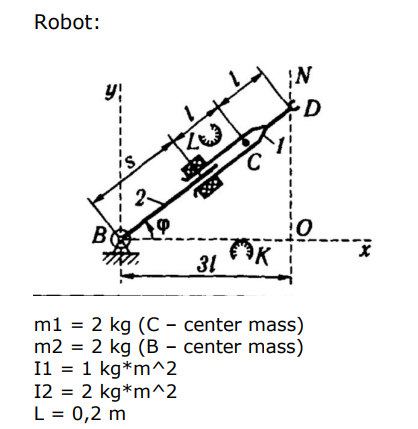

## Question # 1:

### Direct Dynamics

Please note that I will change the numbering of the links. So link 2 will be called link 1 and vice versa!

**STEP 1: Find direct kinematics to the center of mass of each link**


$$O_0 =O_{\textrm{c1}} =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$$



$$\begin{array}{l}
O_{c2} =\left\lbrack \begin{array}{c}
\left(S+l\right)*\cos \left(\phi \right)\\
\left(S+l\right)*\sin \left(\phi \right)\\
0
\end{array}\right\rbrack \\
O_1 =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack 
\end{array}$$


clear all
close all
clc

sympref('FloatingPointOutput',true);

syms q1 q2 dq1 dq2 ddq1 ddq2 real
% s = q2
% phi = q1

m1 = 2;
m2 = 2;
I1 = 1;
I2 = 2;
l = 0.2;

O0 = [0 0 0]';
O1 = O0;
Oc1 = O0;
Oc2 = [(q2+l)*cos(q1) (q2+l)*sin(q1) 0]';
 
T0 = eye(4);
T1 = T0*Rz(q1);
T2 = T1;
T = T2*Tx(q2+2*l);

Z0 = [0 0 1]';
Z1 = T1(1:3,1:3)*[1 0 0]';

**STEP 2: Calculate the jacobians**

As shown here

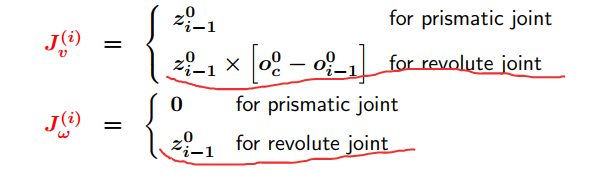

so for linear velocity jacobian we have


$$\begin{array}{l}
J_{\textrm{v1}}^{\left(1\right)} =Z_0^0 \times \left\lbrack O_{\textrm{c1}}^0 -O_0^0 \right\rbrack \\
J_{\textrm{v1}}^{\left(2\right)} =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack \\
J_{\textrm{v2}}^{\left(1\right)} =Z_0^0 \times \left\lbrack O_{\textrm{c2}}^0 -O_0^0 \right\rbrack \\
J_{\textrm{v2}}^{\left(2\right)} =Z_1^0 \times \left\lbrack O_{\textrm{c2}}^0 -O_1^0 \right\rbrack 
\end{array}$$


J1 = [cross(Z0,Oc1-O0);Z0];
J1 = [J1, zeros(6,1)]

J1 =      0     0
     0     0
     0     0
     0     0
     0     0
     1     0


J21 = [cross(Z0,Oc2-O0);Z0];
J22 = [Z1; zeros(3,1)];
J2 = [J21 J22];
simplify(J2);

Jv1 = J1(1:3,:)

Jv1 =      0     0
     0     0
     0     0


Jw1 = J1(4:6,:)

Jw1 =      0     0
     0     0
     1     0


Jv2 = J2(1:3,:)

$$Jv2 = \left(\begin{array}{cc} -\sin\left(q_{1}\right)\,\left(q_{2}+0.2000\right) & \cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\left(q_{2}+0.2000\right) & \sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

Jw2 = J2(4:6,:)

$$Jw2 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$

**STEP 3: Find the inertia matrix D:**

D equals the above expression:

D1 = Dmat(m1,Jv1,Jw1,T1(1:3,1:3),I1);
D2 = Dmat(m2,Jv2,Jw2,T2(1:3,1:3),I2);
D = D1 + D2;
D = simplify(D)

$$D = \left(\begin{array}{cc} 2\,{q_{2}}^{2}+0.8000\,q_{2}+3.0800 & 0\\ 0 & 2 \end{array}\right)$$

**STEP 4: Find coriolos matrix C:**

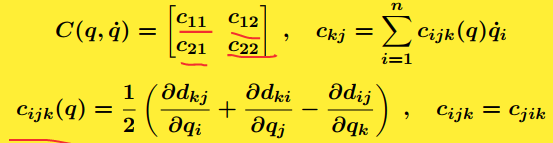

C will be computed using the expression above

q = [q1; q2];
dq = [dq1; dq2];
C = Coriolis(D,q,dq);
C = simplify(C)

$$C = \left(\begin{array}{cc} {\mathrm{dq}}_{2}\,\left(2\,q_{2}+0.4000\right) & {\mathrm{dq}}_{1}\,\left(2\,q_{2}+0.4000\right)\\ -{\mathrm{dq}}_{1}\,\left(2\,q_{2}+0.4000\right) & 0 \end{array}\right)$$

**STEP 5: Find gradient of potential energy matrix G:**

g = [0; 9.81; 0];
P = Pot(m1, g, Oc1) + Pot(m2, g, Oc2);
G = Gmat(P,q);
G = simplify(G)

$$G = \left(\begin{array}{c} 19.6200\,\cos\left(q_{1}\right)\,\left(q_{2}+0.2000\right)\\ 19.6200\,\sin\left(q_{1}\right) \end{array}\right)$$

Dsym = D;
Csym = C;
Gsym = G;

**STEP 6: Test**

### **STABILIZATION TEST (NO CONSTRAINTS - S CAN BE NEGATIVE):**

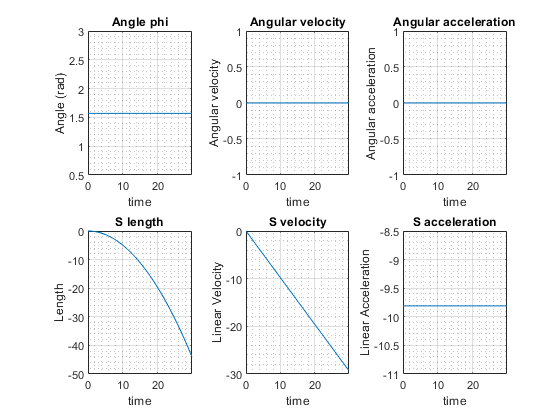

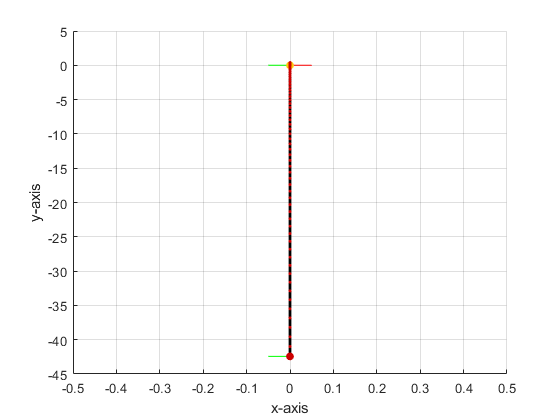

clear ds q1p q2p dq1p dq2p ddq
% initial conditions
q1_0 = pi/2;
q2_0 = 0;
dq1_0 = 0;
dq2_0 = 0;
dt=0.01;
U = [0;0];

% number of samples
n=300;

for i = 1:n
    % Assign Old avlues
    q1p(i)=q1_0;
    q2p(i)=q2_0;
    dq1p(i)=dq1_0;
    dq2p(i)=dq2_0;
    
    % ----------------- BEGIN DYNAMICS MATRICES ------------------------ %
    
    D = [2*q2_0^2 + (4*q2_0)/5 + 77/25, 0; 0, 2];

    C = [dq2_0*(2*q2_0 + 2/5), dq1_0*(2*q2_0 + 2/5); -dq1_0*(2*q2_0 + 2/5), 0]*[dq1_0; dq2_0];
    
    G = [(981*cos(q1_0)*(q2_0 + 1/5))/50; (981*sin(q1_0))/50];
    
    % ----------------- END DYNAMICS MATRICES ------------------------ %

    % Calculate new acceleration value
%     ddq = inv(D(q1_0, q2_0))*(U-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));
    ddq(:,i) = pinv(D)*(U-C-G);
    
    % Update velocity
    dq1_0=dq1p(i) + ddq(1,i)*dt;
    dq2_0=dq2p(i) + ddq(2,i)*dt;
    
    % Update position
    q1_0 = q1p(i) + dq1_0*dt;
    q2_0 = q2p(i) + dq2_0*dt;
    
end

% Removing small errors
qs = [q1p; dq1p; ddq(1,:); q2p; dq2p; ddq(2,:)];
qs = round(qs,15);
t = 0:0.1:(0.1*(n-1));

plotTitles = ["Angle phi", "Angular velocity", "Angular acceleration", "S length", "S velocity", "S acceleration"];
plotYLabels = ["Angle (rad)", "Angular velocity", "Angular acceleration", "Length", "Linear Velocity", "Linear Acceleration"];

for i = 1:6
    subplot(2,3,i)
    plot(t,qs(i,:))
    title(plotTitles(i))
    ylabel(plotYLabels(i))
    xlabel("time")
    grid on
    grid minor
end
% SIMULATION
figure
global axes_plot links_plot joints_plot end_effector_plot
for i = 1:5:length(qs)
    delete([links_plot,joints_plot,end_effector_plot]), delete(axes_plot)
    FK(qs(1,i),qs(4,i),1,0);
    drawnow
    xlim([-2.5*l 2.5*l])
    if i == 1
        pause(1)
    end
end

## Question 2

### Dynamics Equation in Symbolic Form

### 

% sympref('FloatingPointOutput','default');
syms q1 q2 dq1 dq2 ddq1 ddq2 real

qdd = [ddq1 ddq2]';
qd = [dq1 dq2]';

tau = Dsym*qdd + Csym*qd + Gsym

$$tau = \left(\begin{array}{c} 19.6200\,\cos\left(q_{1}\right)\,\left(q_{2}+0.2000\right)+{\mathrm{ddq}}_{1}\,\left(2\,{q_{2}}^{2}+0.8000\,q_{2}+3.0800\right)+2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\left(2\,q_{2}+0.4000\right)\\ \left(-2\,q_{2}-0.4000\right)\,{{\mathrm{dq}}_{1}}^{2}+2\,{\mathrm{ddq}}_{2}+19.6200\,\sin\left(q_{1}\right) \end{array}\right)$$

We can write the final equation in symbolic form as shown in the above equation to be as follow:


$$\left\lbrack \begin{array}{cc}
2q_2^2 +0\ldotp 8q_2 +3\ldotp 08 & 0\\
0 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ddot{q_1 } \\
\ddot{q_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
\dot{q_2 } \left({2q}_2 +0\ldotp 4\right) & \dot{q_1 } \left({2q}_2 +0\ldotp 4\right)\\
-\dot{q_1 } \left({2q}_2 +0\ldotp 4\right) & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{q_1 } \\
\dot{q_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
19\ldotp 62\cdot \mathrm{cos}\left(q_1 \right)\left(q_2 +0\ldotp 2\right)\\
19\ldotp 62\cdot \mathrm{sin}\left(q_1 \right)
\end{array}\right\rbrack =\tau \left(\mathit{\mathbf{t}}\right)=\left\lbrack \begin{array}{c}
\tau \left(t\right)\\
f\left(t\right)
\end{array}\right\rbrack$$


## Question #3

## Applying arbitrary function for the torques and forces of the joints

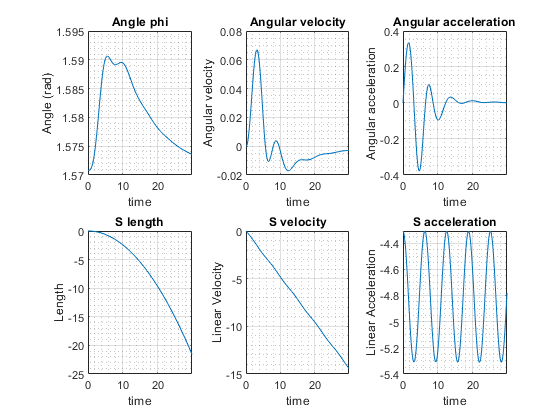

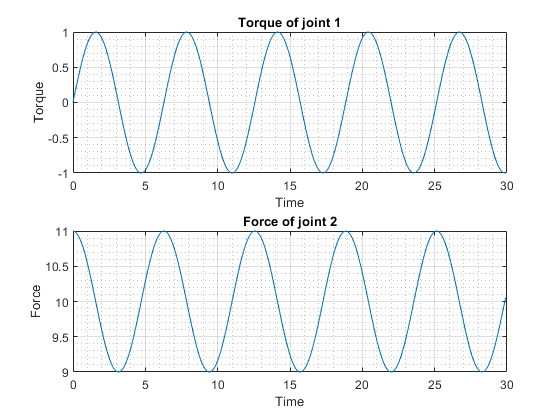

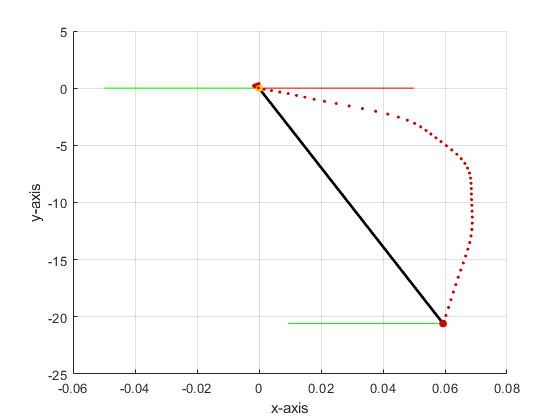

clear ds q1p q2p dq1p dq2p ddq U
% initial conditions
q1_0 = pi/2;
q2_0 = 0;
dq1_0 = 0;
dq2_0 = 0;
dt=0.01;

% number of samples
n=300;
t = 0:0.1:(0.1*(n-1));


% Setting function for the torque of the first joint and the force of the
% second one
% torque function
U(1,:) = sin(t);

% Force function
U(2,:) = cos(t) + 10;

for i = 1:n
    % Assign Old avlues
    q1p(i)=q1_0;
    q2p(i)=q2_0;
    dq1p(i)=dq1_0;
    dq2p(i)=dq2_0;
    

    % ----------------- BEGIN DYNAMICS MATRICES ------------------------ %
    
    D = [2*q2_0^2 + (4*q2_0)/5 + 77/25, 0; 0, 2];

    C = [dq2_0*(2*q2_0 + 2/5), dq1_0*(2*q2_0 + 2/5); -dq1_0*(2*q2_0 + 2/5), 0]*[dq1_0; dq2_0];
    
    G = [(981*cos(q1_0)*(q2_0 + 1/5))/50; (981*sin(q1_0))/50];
    
    % ----------------- END DYNAMICS MATRICES ------------------------ %

    % Calculate new acceleration value
%     ddq = inv(D(q1_0, q2_0))*(U-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));
    ddq(:,i) = pinv(D)*(U(:,i)-C-G);
    
        
    % Update velocity
    dq1_0=dq1p(i) + ddq(1,i)*dt;
    dq2_0=dq2p(i) + ddq(2,i)*dt;
    
    % Update position
    q1_0 = q1p(i) + dq1_0*dt;
    q2_0 = q2p(i) + dq2_0*dt;
    


end

% Removing small errors
qs = [q1p; dq1p; ddq(1,:); q2p; dq2p; ddq(2,:)];
qs = round(qs,15);

for i = 1:6
    subplot(2,3,i)
    plot(t,qs(i,:))
    title(plotTitles(i))
    ylabel(plotYLabels(i))
    xlabel("time")
    grid on
    grid minor
end

figure
subplot(2,1,1)
plot(t,U(1,:))
title("Torque of joint 1")
ylabel("Torque"),xlabel("Time")
grid on, grid minor

subplot(2,1,2)
plot(t,U(2,:))
title("Force of joint 2")
ylabel("Force"),xlabel("Time")
grid on, grid minor

% SIMULATION
figure
global axes_plot links_plot joints_plot end_effector_plot
for i = 1:5:length(qs)
    delete([links_plot,joints_plot,end_effector_plot]), delete(axes_plot)
    FK(qs(1,i),qs(4,i),1,0);
    drawnow
    if i == 1
        pause(1)
    end
end


clear U

# **TESTS**

### **TEST #1 - STABILIZATION TEST (CONSTRAINED - S CANNOT BE NEGATIVE):**

clear ds q1p q2p dq1p dq2p ddq
% initial conditions
q1_0 = pi/2;
q2_0 = 0;
dq1_0 = 0;
dq2_0 = 0;
dt=0.01;
U = [0;0];

% number of samples
n=300;

for i = 1:n
    % Assign Old avlues
    q1p(i)=q1_0;
    q2p(i)=q2_0;
    dq1p(i)=dq1_0;
    dq2p(i)=dq2_0;
    
    % ----------------- BEGIN DYNAMICS MATRICES ------------------------ %
    
    D = [2*q2_0^2 + (4*q2_0)/5 + 77/25, 0; 0, 2];

    C = [dq2_0*(2*q2_0 + 2/5), dq1_0*(2*q2_0 + 2/5); -dq1_0*(2*q2_0 + 2/5), 0]*[dq1_0; dq2_0];
    
    G = [(981*cos(q1_0)*(q2_0 + 1/5))/50; (981*sin(q1_0))/50];
    
    % ----------------- END DYNAMICS MATRICES ------------------------ %

    % Calculate new acceleration value
%     ddq = inv(D(q1_0, q2_0))*(U-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));
    ddq(:,i) = pinv(D)*(U-C-G);
    
    if q2_0 <= 0 && ddq(2,i) < 0
        ddq(2,i) = 0;
        dq2p(i) =0 ;
        q2p(i) = 0;
    end
        
    % Update velocity
    dq1_0=dq1p(i) + ddq(1,i)*dt;
    dq2_0=dq2p(i) + ddq(2,i)*dt;
    
    % Update position
    q1_0 = q1p(i) + dq1_0*dt;
    q2_0 = q2p(i) + dq2_0*dt;
    


end

% Removing small errors
qs = [q1p; dq1p; ddq(1,:); q2p; dq2p; ddq(2,:)];
qs = round(qs,15);
t = 0:0.1:(0.1*(n-1));

for i = 1:6
    subplot(2,3,i)
    plot(t,qs(i,:))
    title(plotTitles(i))
    ylabel(plotYLabels(i))
    xlabel("time")
    grid on
    grid minor
end
% SIMULATION
figure
global axes_plot links_plot joints_plot end_effector_plot
for i = 1:5:length(qs)
    delete([links_plot,joints_plot,end_effector_plot]), delete(axes_plot)
    FK(qs(1,i),qs(4,i),1,0);
    xlim([-2.5*l 2.5*l])
    drawnow
    if i == 1
        pause(1)
    end
end

### **TEST #2 - PENDULUM TEST (CONSTRAINED - CONSTANT S):**

clear ds q1p q2p dq1p dq2p ddq
% initial conditions
q1_0 = pi/3;
q2_0 = 0;
dq1_0 = 0;
dq2_0 = 0;
dt=0.01;
U = [0;0];

% number of samples
n=2500;

for i = 1:n
    % Assign Old avlues
    q1p(i)=q1_0;
    q2p(i)=q2_0;
    dq1p(i)=dq1_0;
    dq2p(i)=dq2_0;
    
    % ----------------- BEGIN DYNAMICS MATRICES ------------------------ %
    
    D = [2*q2_0^2 + (4*q2_0)/5 + 77/25, 0; 0, 2];

    C = [dq2_0*(2*q2_0 + 2/5), dq1_0*(2*q2_0 + 2/5); -dq1_0*(2*q2_0 + 2/5), 0]*[dq1_0; dq2_0];
    
    G = [(981*cos(q1_0)*(q2_0 + 1/5))/50; (981*sin(q1_0))/50];
    
    % ----------------- END DYNAMICS MATRICES ------------------------ %

    % Calculate new acceleration value
%     ddq = inv(D(q1_0, q2_0))*(U-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));
    ddq(:,i) = pinv(D)*(U-C-G);

    % TEEEEST !!!
    % Fixed length link
    ddq(2,i) = 0;
    % Update velocity
    dq1_0=dq1p(i) + ddq(1,i)*dt;
    dq22_0=dq2p(i) + ddq(2,i)*dt;
    
    % Update position
    q1_0 = q1p(i) + dq1_0*dt;
    q22_0 = q2p(i) + dq2_0*dt;
end

% Removing small errors
qs = [q1p; dq1p; ddq(1,:); q2p; dq2p; ddq(2,:)];
qs = round(qs,15);
t = 0:0.1:(0.1*(n-1));

for i = 1:6
    subplot(2,3,i)
    plot(t,qs(i,:))
    title(plotTitles(i))
    ylabel(plotYLabels(i))
    xlabel("time")
    grid on
    grid minor
end
% SIMULATION
figure
global axes_plot links_plot joints_plot end_effector_plot
for i = 1:25:length(qs)
    delete([links_plot,joints_plot,end_effector_plot]), delete(axes_plot)
    FK(qs(1,i),qs(4,i),1,0);
    
    axis([-2.5*l 2.5*l -2.5*l 2.5*l])
    drawnow
    if i == 1
        pause(1)
    end
end

### **TEST #3 - SECOND PENDULUM TEST (CONSTRAINED - CONSTANT S + MOTOR TORQUE INCREASES WITH TIME):**

clear ds q1p q2p dq1p dq2p ddq
% initial conditions
q1_0 = pi/3;
q2_0 = 0;
dq1_0 = 0;
dq2_0 = 0;
dt=0.01;
U = [0;0];

% number of samples
n=2500;

for i = 1:n
    % Assign Old avlues
    q1p(i)=q1_0;
    q2p(i)=q2_0;
    dq1p(i)=dq1_0;
    dq2p(i)=dq2_0;
    U(1) = U(1) + i/10000;
    
    % ----------------- BEGIN DYNAMICS MATRICES ------------------------ %
    
    D = [2*q2_0^2 + (4*q2_0)/5 + 77/25, 0; 0, 2];

    C = [dq2_0*(2*q2_0 + 2/5), dq1_0*(2*q2_0 + 2/5); -dq1_0*(2*q2_0 + 2/5), 0]*[dq1_0; dq2_0];
    
    G = [(981*cos(q1_0)*(q2_0 + 1/5))/50; (981*sin(q1_0))/50];
    
    % ----------------- END DYNAMICS MATRICES ------------------------ %

    % Calculate new acceleration value
%     ddq = inv(D(q1_0, q2_0))*(U-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));
    ddq(:,i) = pinv(D)*(U-C-G);

    % TEEEEST !!!
    % Fixed length link
    ddq(2,i) = 0;
    % Update velocity
    dq1_0=dq1p(i) + ddq(1,i)*dt;
    dq22_0=dq2p(i) + ddq(2,i)*dt;
    
    % Update position
    q1_0 = q1p(i) + dq1_0*dt;
    q22_0 = q2p(i) + dq2_0*dt;
end

% Removing small errors
qs = [q1p; dq1p; ddq(1,:); q2p; dq2p; ddq(2,:)];
qs = round(qs,15);
t = 0:0.1:(0.1*(n-1));

for i = 1:6
    subplot(2,3,i)
    plot(t,qs(i,:))
    title(plotTitles(i))
    ylabel(plotYLabels(i))
    xlabel("time")
    grid on
    grid minor
end
% SIMULATION
figure
global axes_plot links_plot joints_plot end_effector_plot
for i = 1:5:length(qs)
    delete([links_plot,joints_plot,end_effector_plot]), delete(axes_plot)
    FK(qs(1,i),qs(4,i),1,0);
    
    axis([-2.5*l 2.5*l -2.5*l 2.5*l])
    drawnow
    if i == 1
        pause(1)
    end
end
